% 定义完整输入参数
inputs = struct(...
    'gas', struct('k', 1.4, 'R', 287), ...
    'inlet', struct('T', 288, 'p', 101325, 'c', 100), ...
    'outlet_pressure', 500000, ...
    'mass_flow', 100, ...
    'stages', 10, ...
    'efficiency', struct('ad', 0.92, 'mech', 0.96, 'leak', 0.99), ...
    'u', 250, ...
    'reaction_coeff', [0.45, 0.48, 0.50, 0.52, 0.55, 0.58, 0.60, 0.62, 0.65, 0.68] ... % 用户自定义反动度分布
);

% 创建压缩机对象
compressor = AxialCompressor(inputs);

% 进行计算
results = compressor.calculate();

% 显示详细级结果
compressor.display_stage_results(results);


=== 轴流压缩机逐级计算结果 ===
级数: 10
总压比: 6.89
总温升: 190.34 K
总耗功: 19119.72 kW

--- 第1级 ---
  进口温度: 288.00 K
  出口温度: 307.03 K
  进口压力: 101.33 kPa
  出口压力: 129.26 kPa
  压比: 1.276
  温升: 19.03 K
  进口速度: 100.00 m/s
  出口速度: 83.57 m/s
  反动度: 0.450
  级功率: 1911.97 kW

--- 第2级 ---
  进口温度: 307.03 K
  出口温度: 326.07 K
  进口压力: 129.26 kPa
  出口压力: 162.49 kPa
  压比: 1.257
  温升: 19.03 K
  进口速度: 83.57 m/s
  出口速度: 70.60 m/s
  反动度: 0.480
  级功率: 1911.97 kW

--- 第3级 ---
  进口温度: 326.07 K
  出口温度: 345.10 K
  进口压力: 162.49 kPa
  出口压力: 201.64 kPa
  压比: 1.241
  温升: 19.03 K
  进口速度: 70.60 m/s
  出口速度: 60.21 m/s
  反动度: 0.500
  级功率: 1911.97 kW

--- 第4级 ---
  进口温度: 345.10 K
  出口温度: 364.14 K
  进口压力: 201.64 kPa
  出口压力: 247.33 kPa
  压比: 1.227
  温升: 19.03 K
  进口速度: 60.21 m/s
  出口速度: 51.80 m/s
  反动度: 0.520
  级功率: 1911.97 kW

--- 第5级 ---
  进口温度: 364.14 K
  出口温度: 383.17 K
  进口压力: 247.33 kPa
  出口压力: 300.23 kPa
  压比: 1.214
  温升: 19.03 K
  进口速度: 51.80 m/s
  出口速度: 44.90 m/s
  反动度: 0.550
  级功率: 1911.97 kW

--- 第6级 ---
  进口温度: 383.17 K
  出口温度: 40

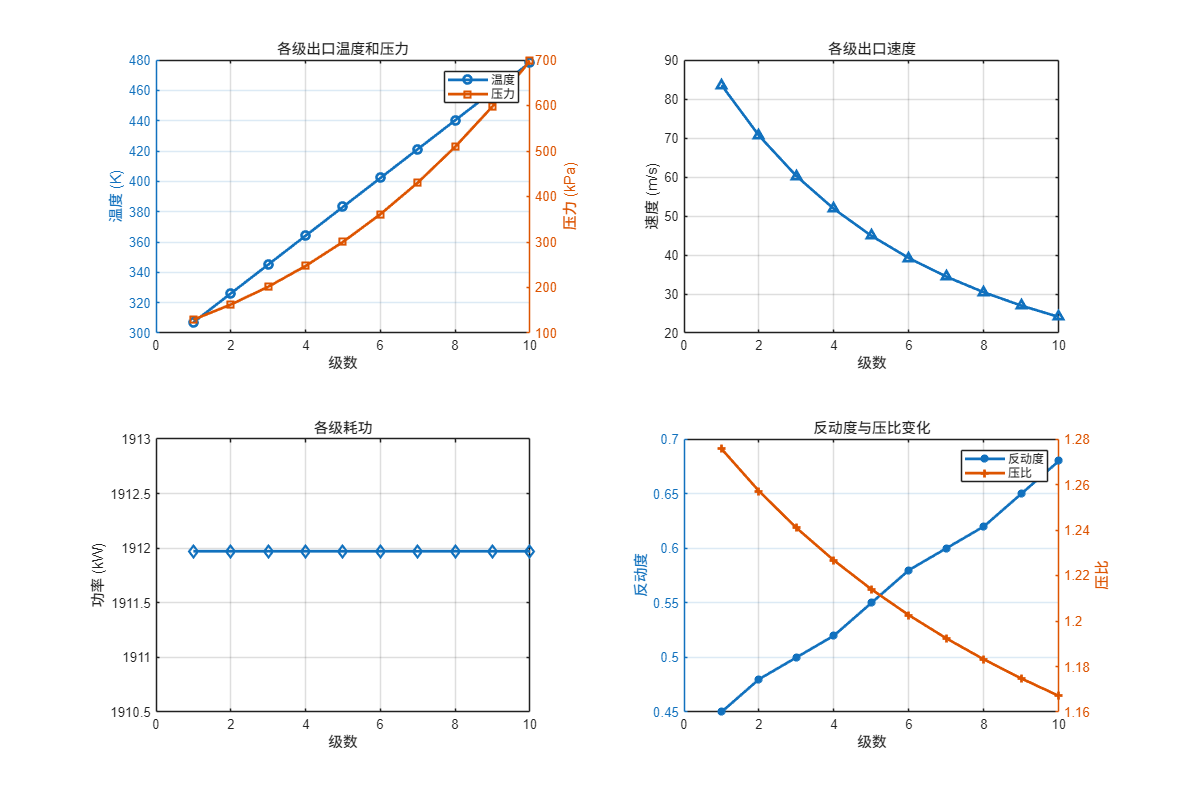


% 绘制性能曲线
compressor.plot_performance(results);